# Simulate box's trajectory and track it 

Specifying all parameters, boh for simulation (_sim) and for the Extended Kalman Filter

clear
%rng(1);    % For repeatable results

m=0.5;%Kg for the box, from PyBullet simulation 
dt=0.005; %200Hz, 466Hz
flux = 0.7;%Target hitting flux of the robot, form PyBullet simulation
sigma_2=0.01; %Standard deviation of gaussian Hitting Force model
processNoise = diag([0; 0; 0; 0; 0 ; 0]); % No process noise in this model, but from report : Process noise matrix diag([0.01; 0.1; 0.14; 0.01])

## Import data form Pybullet simulation

filename = 'log_box_traj.txt';
delimiterIn = ' ';
sim_data = importdata(filename,delimiterIn)';

simTime = dt*length(sim_data)

simTime = 1.6300

tspan   = dt:dt:simTime;
numSteps = length(tspan);
trueStates = NaN(1,numSteps);
trueStates(1,:) = sim_data(3,:);
trueStates(2,:) = trueStates(1,:)-sim_data(6,:)-0.15; %There is a 15cm offset betwwen End_effector and the center of the box

Plot the true trajectory

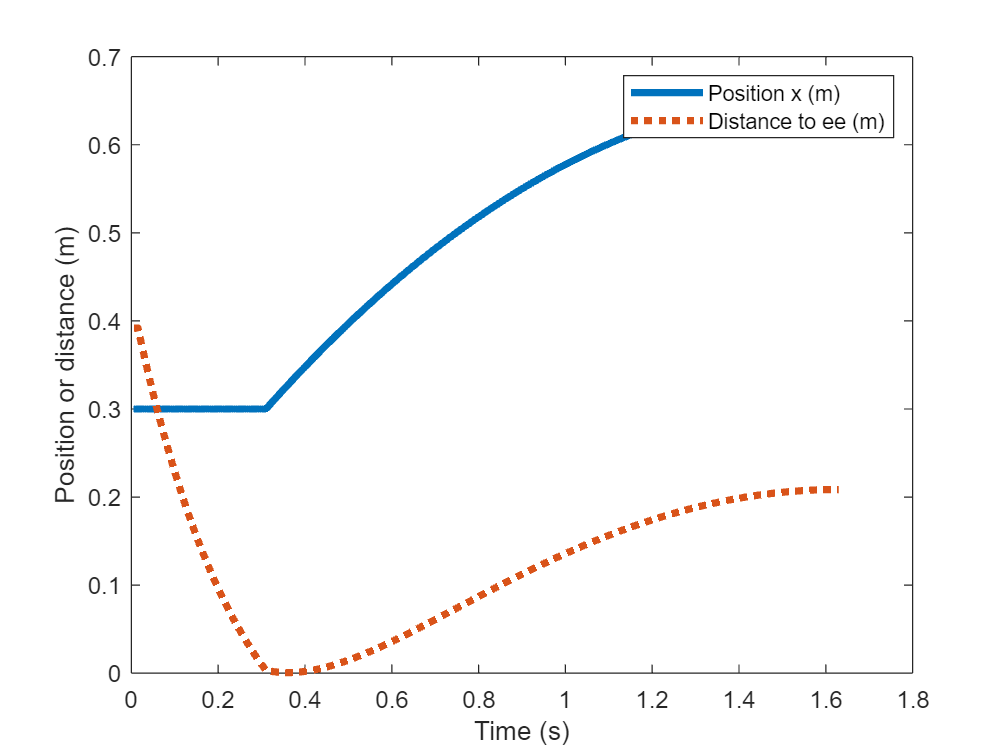

figure
plot(tspan,trueStates(1,:),"-",'LineWidth',3,DisplayName="Position x (m)")
hold on
plot(tspan,trueStates(2,:),":",'LineWidth',3,DisplayName="Distance to ee (m)")
ylabel("Position or distance (m)")
xlabel("Time (s)")
legend

## Initialize Extended Kalman Filter

Initialize the filter

n=7;        %number of state
q=0.001;    %std of process 
r=0.05;     %std of measurement
Q=q^2*eye(n);   %covariance of process
R=r^2;          %covariance of measurement
phi = flux;     %Known Hitting Flux
s=[trueStates(1,1);0;0;0; trueStates(2,1); 0.5; 0.5]; %Initial state for [X;V;Ff;Fh;d;mu;e]
x=s+q*randn(n,1);               % initial state with noise
P = eye(n);                               % initial state covariance

estimateStates = NaN(n,numSteps);
Xf_pred = NaN(1,numSteps);

for k=1:numSteps
  z = trueStates([1 2],k) + r*randn;        % measurements
  [x, P] = ekf(x,P,z,Q,R,dt,m,phi,sigma_2); % ekf 
  estimateStates(:,k) = x;                % save estimate
  Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (x(6) * 9.81));
end

## Run Kalman Filter and Show Results

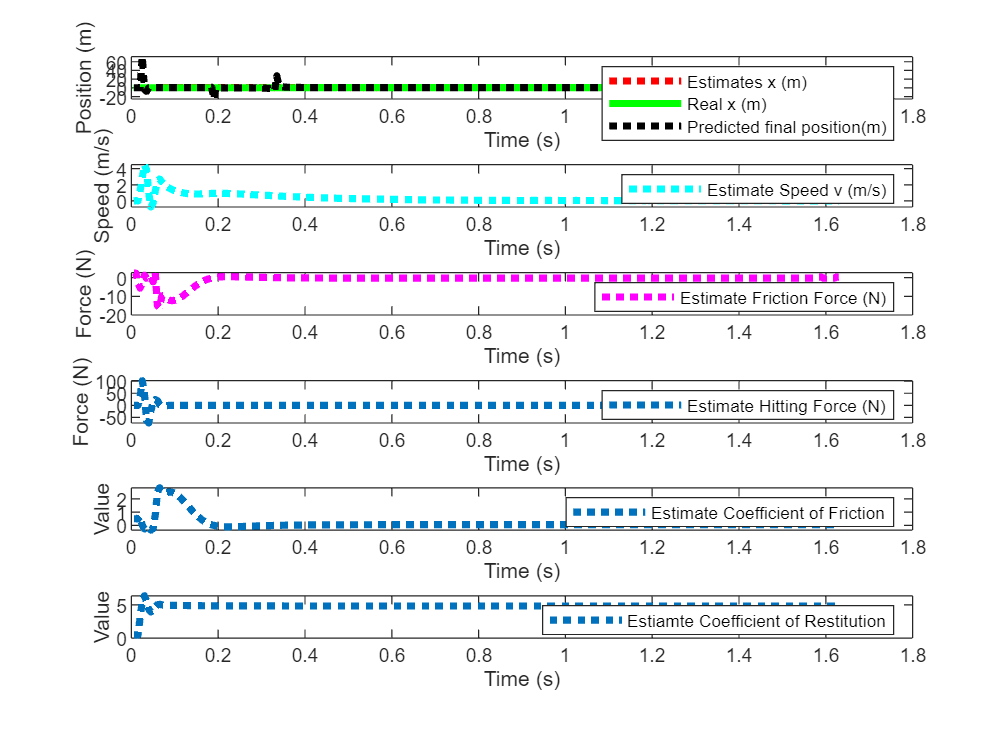

figure

subplot(6,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,3)
plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,4)
plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")
subplot(6,1,5)
plot(tspan,estimateStates(6,:),":",'LineWidth',3,DisplayName="Estimate Coefficient of Friction")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,6)
plot(tspan,estimateStates(7,:),":",'LineWidth',3,DisplayName="Estiamte Coefficient of Restitution")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")

## New parameters for the EKF, from the last run (e and mu)

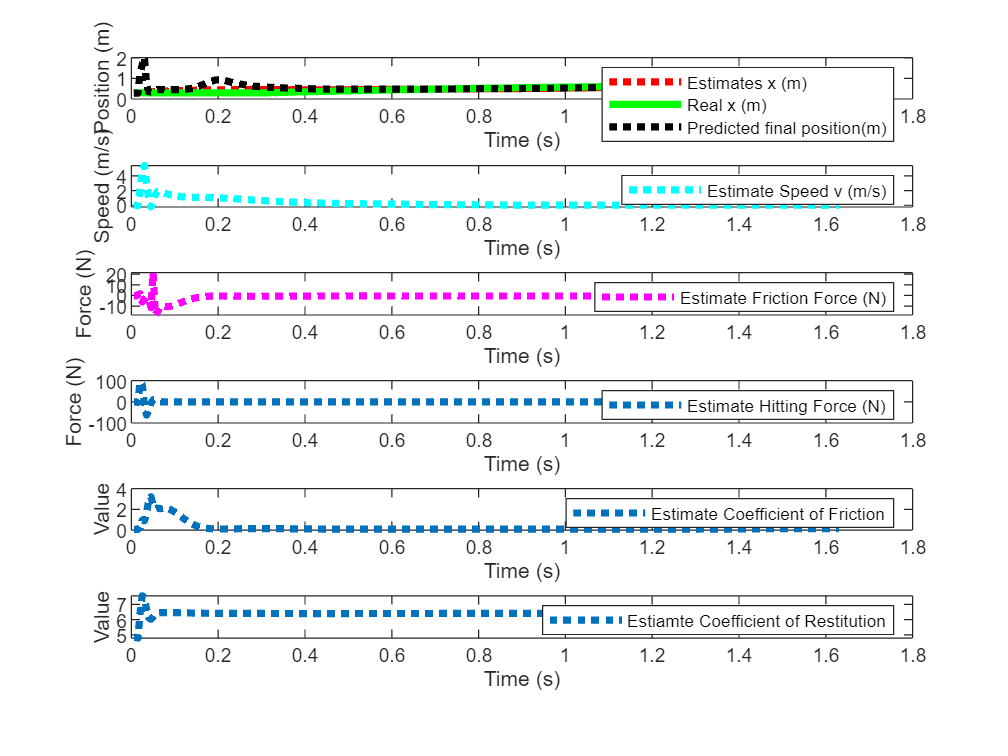

s=[trueStates(1,1);0;0;0; trueStates(2,1); estimateStates(6,end); estimateStates(7,end)]; % initial state
estimateStates = NaN(n,numSteps);
Xf_pred = NaN(1,numSteps);

x=s+q*randn(n,1); %initial state          % initial state with noise
P = eye(n);                               % initial state covariance

for k=1:numSteps
  z = trueStates([1 2],k) + r*randn;        % measurements
  [x, P] = ekf(x,P,z,Q,R,dt,m,phi,sigma_2); % ekf 
  estimateStates(:,k) = x;                % save estimate
  Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (x(6) * 9.81));
end

figure

subplot(6,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,3)
plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,4)
plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")
subplot(6,1,5)
plot(tspan,estimateStates(6,:),":",'LineWidth',3,DisplayName="Estimate Coefficient of Friction")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")

subplot(6,1,6)
plot(tspan,estimateStates(7,:),":",'LineWidth',3,DisplayName="Estiamte Coefficient of Restitution")
ylabel("Value")
xlabel("Time (s)")
legend(Location="southeast")


%EKF Functions
% By Yi Cao at Cranfield University, 02/01/2008
%
function [x,P]=ekf(x,P,z,Q,R,dt,m,phi,sigma_2)
% EKF   Extended Kalman Filter for nonlinear dynamic systems
% [x, P] = ekf(f,x,P,h,z,Q,R) returns state estimate, x and state covariance, P 
% for nonlinear dynamic system:
%           x_k+1 = f(x_k) + w_k
%           z_k   = h(x_k) + v_k
% where w ~ N(0,Q) meaning w is gaussian noise with covariance Q
%       v ~ N(0,R) meaning v is gaussian noise with covariance R
% Inputs:   f: function handle for f(x)
%           x: "a priori" state estimate
%           P: "a priori" estimated state covariance
%           h: fanction handle for h(x)
%           z: current measurement
%           Q: process noise covariance 
%           R: measurement noise covariance
% Output:   x: "a posteriori" state estimate
%           P: "a posteriori" state covariance
%

[x1,A]=jaccsd(x,dt,m,phi,sigma_2);    %nonlinear update and linearization at current state
P=A*P*A'+Q;                 %partial update
H = [1 0 0 0 0 0 0;
     0 0 0 0 1 0 0];
z1 = [x(1); x(5)];          %Expected Observation
P12=P*H';                   %cross covariance
%H*P12+R
%K=P12*pinv(H*P12+R);       %Kalman filter gain
%x=x1+K*(z-z1);            %state estimate
%P=P-K*P12';               %state covariance matrix
R=chol(H*P12+R);            %Cholesky factorization
U=P12/R;                    %K=U/R'; Faster because of back substitution
x=x1+U*(R'\(z-z1));         %Back substitution to get state update
P=P-U*U';                   %Covariance update, U*U'=P12/R/R'*P12'=K*P12.
end

function [z,A]=jaccsd(x,dt,m,phi,sigma_2)
% JACCSD Jacobian through complex step differentiation
% [z J] = jaccsd(f,x)
% z = f(x)
% J = f'(x)
%
z=f(x,m,dt,phi,sigma_2);
%x, v, Ff, Fh, d, mu, e
sigma_1_k = ((phi^2*m*(1+x(7))^2)/(2*sigma_2*sqrt(2*pi)));
A=[1 dt (dt^2)/(2*m) (dt^2)/(2*m) 0 0 0;
   0 1 dt/m dt/m 0 0 0;
   0 -m*9.81*x(6)*sign(x(2)) 0 0 0 -m*9.81*sign(x(2)) 0;
   0 0 0 0 -sigma_1_k*abs(x(5)/sigma_2^2)*exp(-x(5)^2 / (2*sigma_2^2)) 0 (2*x(7)+2)*(m*phi^2)/(2*sigma_2*sqrt(2*pi));
   0 0 0 0 1 0 0;
   0 0 0 0 0 1 0;
   0 0 0 0 0 0 1]; 
end

function y=f(x,m,dt,phi,sigma_2)
sigma_1_k = ((phi^2*m*(1+x(7))^2)/(2*sigma_2*sqrt(2*pi)));
y = [x(1)+dt*x(2)+((dt*dt)/(2*m) * (x(3) + x(4)));
     x(2) + (dt/m) * (x(3) + x(4));
     -m*9.81*x(6)*sign(x(2));
     sigma_1_k*exp(-x(5)^2 / (2*sigma_2^2));
     x(5);
     x(6);
     x(7)];% nonlinear state equations
end

*Copyright 2021 The MathWorks, Inc.*